c = readtable("clean_data/image_cts.csv")

c = 2244×1 table
    ids
    ___

     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     2 
     2 
     2 
     2 


t = readtable("clean_data/labels.csv")

t = 267×54 table
    ID               NewName                            Name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

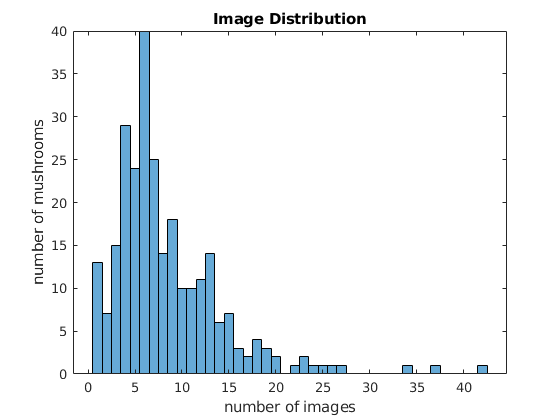


h = histcounts(c.ids, length(unique(c.ids)));
[counts, idx] = sort(h);
histogram(counts)
xlabel("number of images")
ylabel("number of mushrooms")
title("Image Distribution")

writetable(t(counts <= 2, ["ID","NewName", "Name"]), "clean_data/lowest_image_counts.csv")
